## Problem 1

Constants

mu = 398600; %km^3/s^2
a = 6600; %km
n = sqrt(mu/a^3); %1/s

Problem 1a

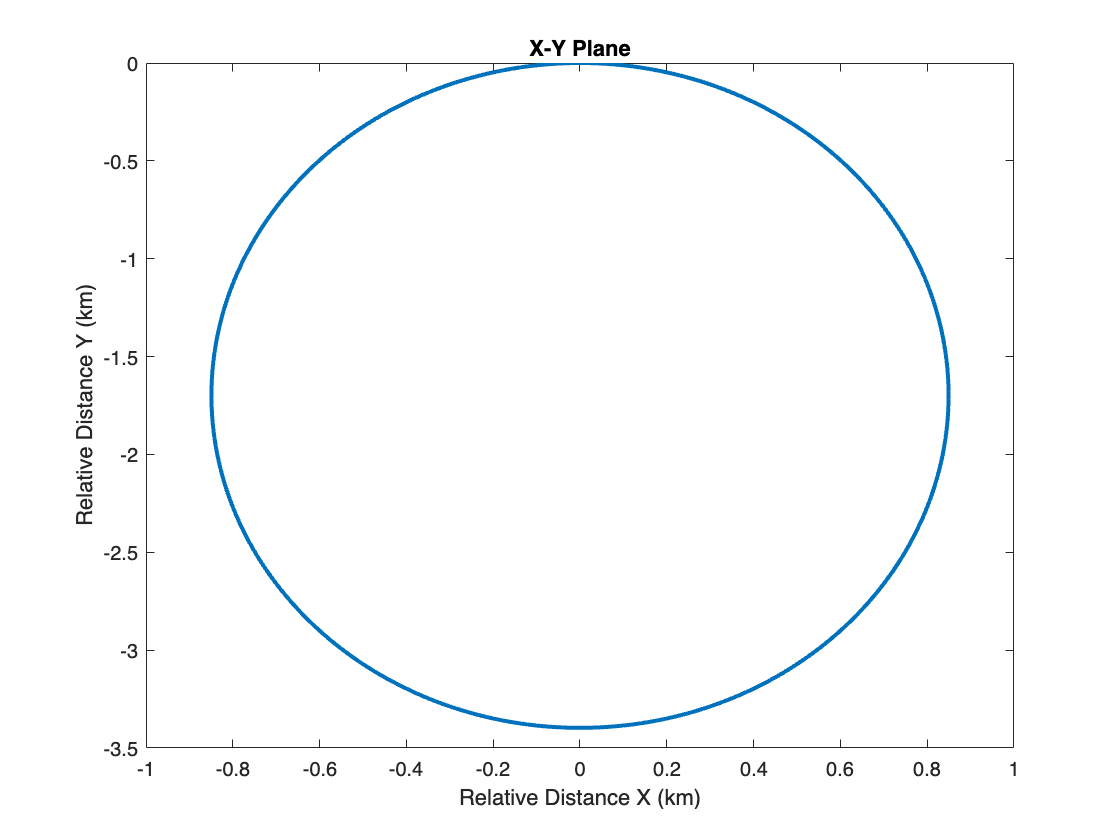

x0 = 0; %km
y0 = 0; %km
z0 = 0; %km
xdot0 = 1e-3; %km/s
ydot0 = 0; %km/s
zdot0 = 0; %km/s

tspan = linspace(0,100*60,5*60);
X = cw([x0;y0;z0;xdot0;ydot0;zdot0],n,tspan);

plot(X(:,1),X(:,2),'LineWidth',2)
title("X-Y Plane")
xlabel("Relative Distance X (km)")
ylabel("Relative Distance Y (km)")

Problem 1b

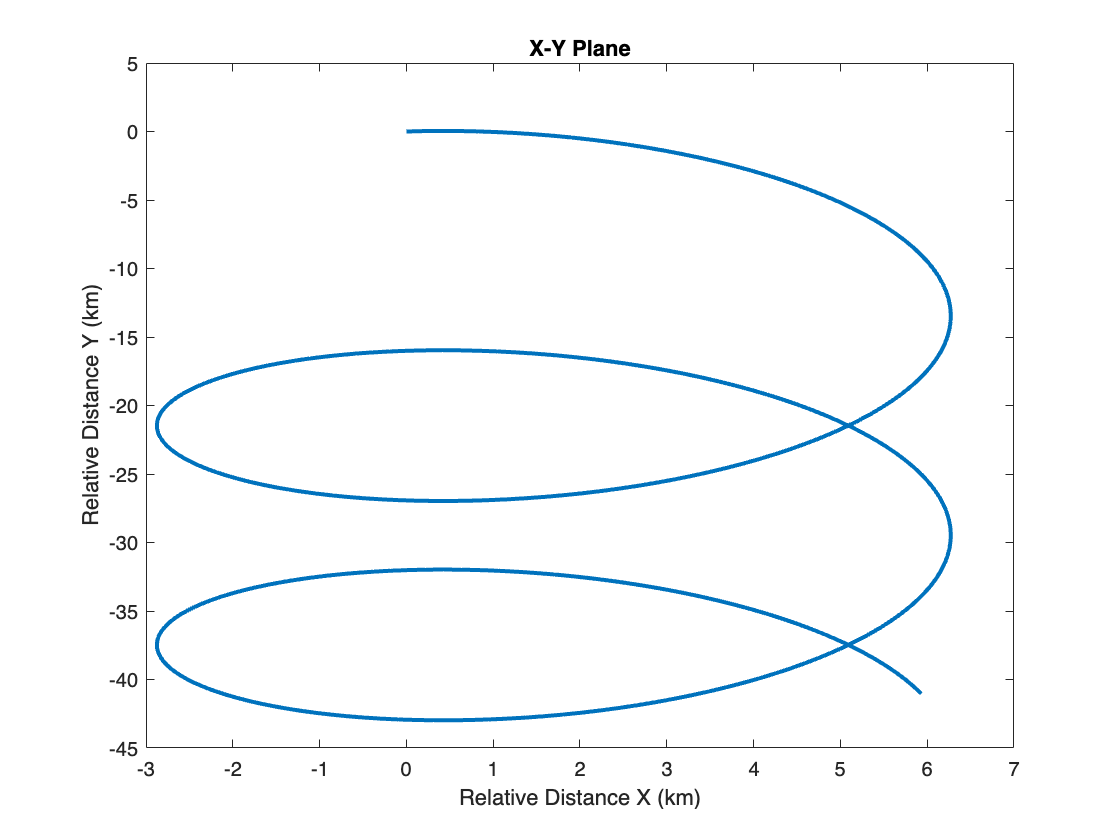

x0 = 0; %km
y0 = 0; %km
z0 = 0; %km
xdot0 = 5e-3; %km/s
ydot0 = 1e-3; %km/s
zdot0 = 0; %km/s

tspan = linspace(0,200*60,5*60);
X = cw([x0;y0;z0;xdot0;ydot0;zdot0],n,tspan);

plot(X(:,1),X(:,2),'LineWidth',2)
title("X-Y Plane")
xlabel("Relative Distance X (km)")
ylabel("Relative Distance Y (km)")

Problem 1c

r0 = [500; 600; 200]; %m
r = [0; 0; 0]; %m
t = 60*60; %s

A = [(4 - 3*cos(n*t)) 0 0;
    6*(sin(n*t) - n*t) 1 0;
    0 0 cos(n*t)];
B = [sin(n*t)/n 2/n*(1 - cos(n*t)) 0;
    2/n*(cos(n*t) - 1) 1/n*(4*sin(n*t) - 3*n*t) 0;
    0 0 sin(n*t)/n];

v0 = B\(r - A*r0) %m/s

v0 =     0.0322
   -1.0754
   -0.1207


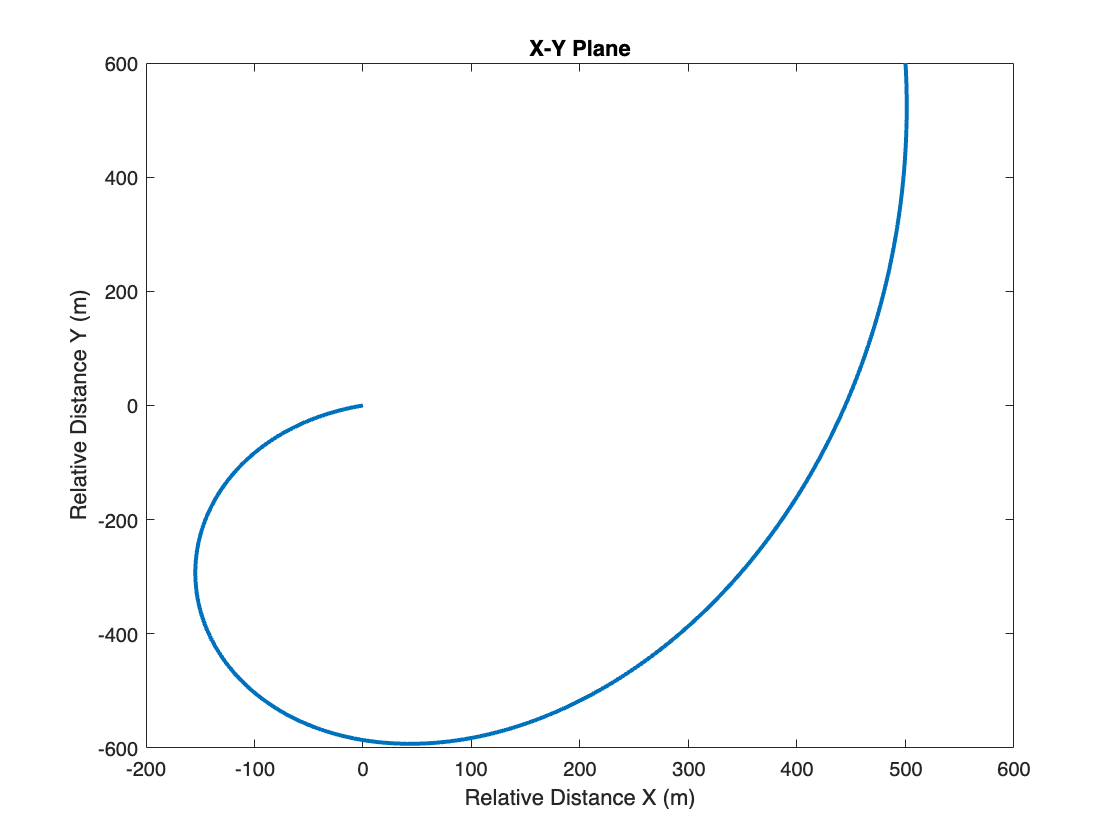

tspan = linspace(0,t,5*60);
X = cw([r0;v0],n,tspan);

plot(X(:,1),X(:,2),'LineWidth',2)
title("X-Y Plane")
xlabel("Relative Distance X (m)")
ylabel("Relative Distance Y (m)")

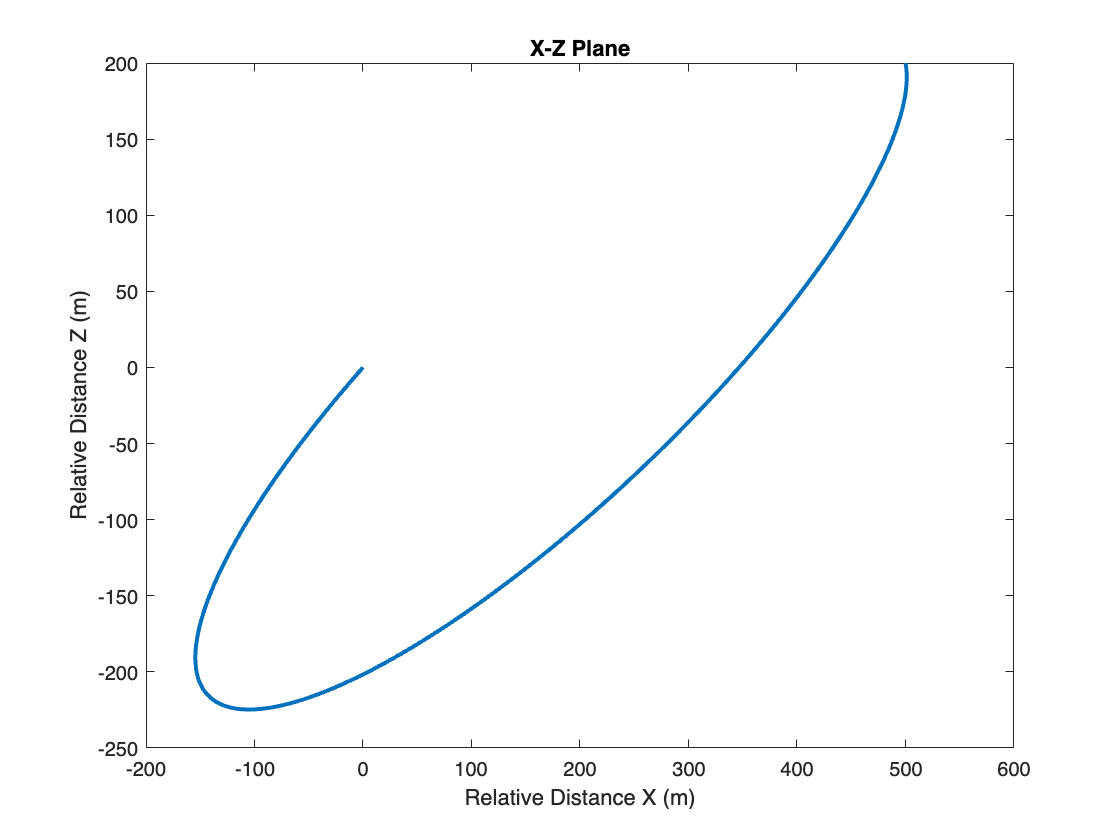

plot(X(:,1),X(:,3),'LineWidth',2)
title("X-Z Plane")
xlabel("Relative Distance X (m)")
ylabel("Relative Distance Z (m)")

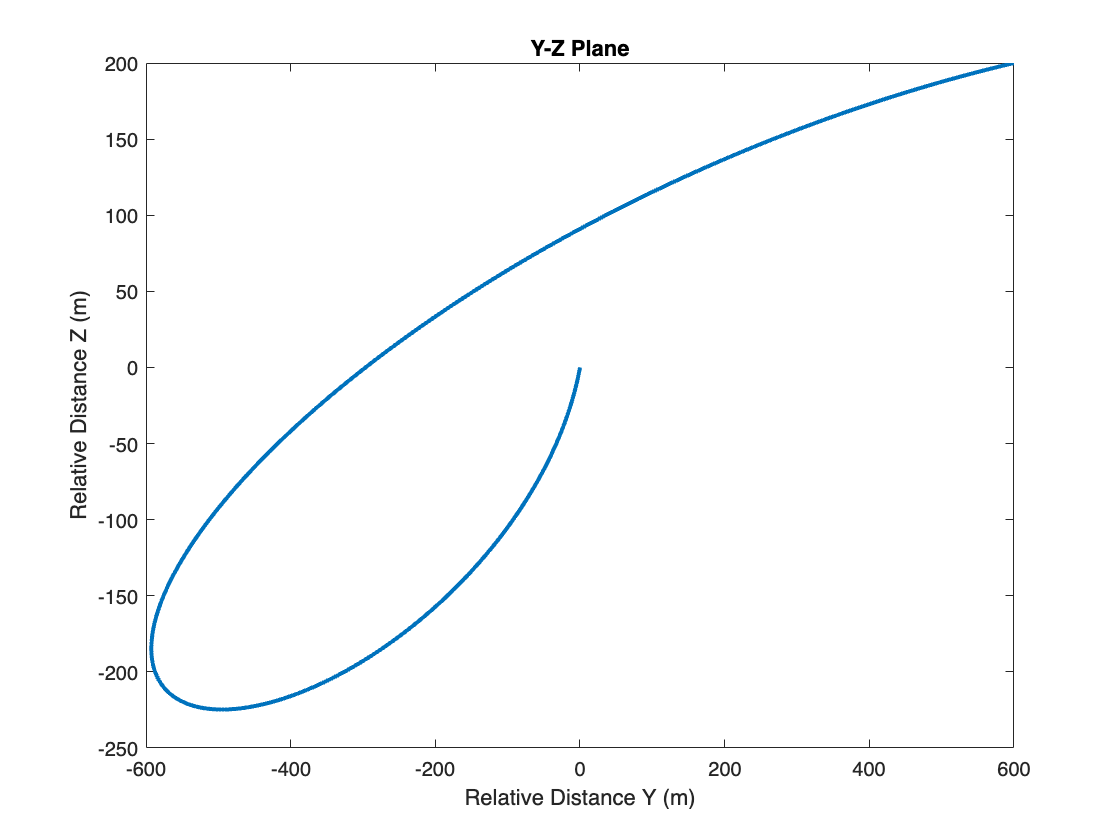

plot(X(:,2),X(:,3),'LineWidth',2)
title("Y-Z Plane")
xlabel("Relative Distance Y (m)")
ylabel("Relative Distance Z (m)")

X(end,4:6) %m/s

ans =     0.3277    0.1020    0.2646


Needed final velocity: V = [-0.3277; -0.1020; -0.2646] m/s

function X = cw(X0,n,tspan)
A = @(t) [(4 - 3*cos(n*t)) 0 0;
    6*(sin(n*t) - n*t) 1 0;
    0 0 cos(n*t)];
B = @(t) [sin(n*t)/n 2/n*(1 - cos(n*t)) 0;
    2/n*(cos(n*t) - 1) 1/n*(4*sin(n*t) - 3*n*t) 0;
    0 0 sin(n*t)/n];
C = @(t) [3*n*sin(n*t) 0 0;
    6*n*(cos(n*t) - 1) 0 0;
    0 0 -n*sin(n*t)];
D = @(t) [cos(n*t) 2*sin(n*t) 0;
    -2*sin(n*t) (4*cos(n*t) - 3) 0;
    0 0 cos(n*t)];

X = zeros(length(tspan),6);
for i = 1:length(tspan)
    t = tspan(i);
    Xtemp = [A(t) B(t); C(t) D(t)]*X0;
    X(i,:) = transpose(Xtemp);
end
end